# Latest Avengers movie from the saga!

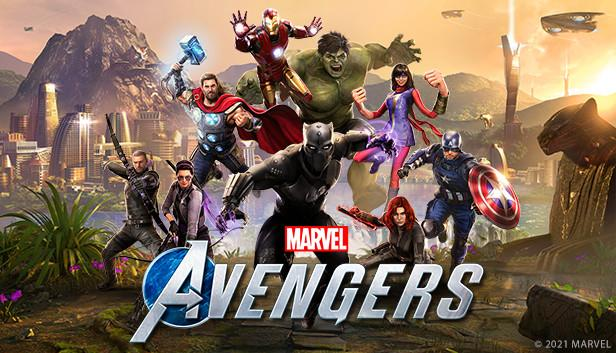

Avengers is a series of movies where multiple superheroes from the Marvel universe unite to challenge tenacious antagonists from the Marvel universe. Avengers movie unifies all Marvel fans as there is a chance of new strong comic characters appearing on the stage and the satisfaction of viewing their superheroes in action. To learn more click [here](https://marvelcinematicuniverse.fandom.com/wiki/Avengers).

load database

Avengers = search_for_movie(movies,'Avengers');

num_aven_movies = length(Avengers);


latest_movie = Avengers(end);
latest_movie_title = movies(latest_movie).title;
 
movie_director = movie_directors(directors,latest_movie);

movie_director_name = {};

for ii = 1:length(movie_director)
    movie_director_name{end+1} = persons(movie_director(ii)).name;
end

r = r_rated(movies);

cast = movie_cast(actors,latest_movie);
person_tog = persons(cast(1)).name;

together = length(actor_directed_by(directors,actors,movie_director(1),cast(1)));

attributes_countries = length(countries(movies));

most_acting = most_self_directed(directors,actors);

ratings = ratings_per_year(movies);

fprintf('Based on the online database, there are %d Avengers movies upto today.' ...
    ,(num_aven_movies))

Based on the online database, there are 4 Avengers movies upto today.


fprintf('The latest Avengers movie is %s released on %s.',(latest_movie_title),movies(latest_movie).release)

The latest Avengers movie is Avengers: Endgame released on 2019-04-24.

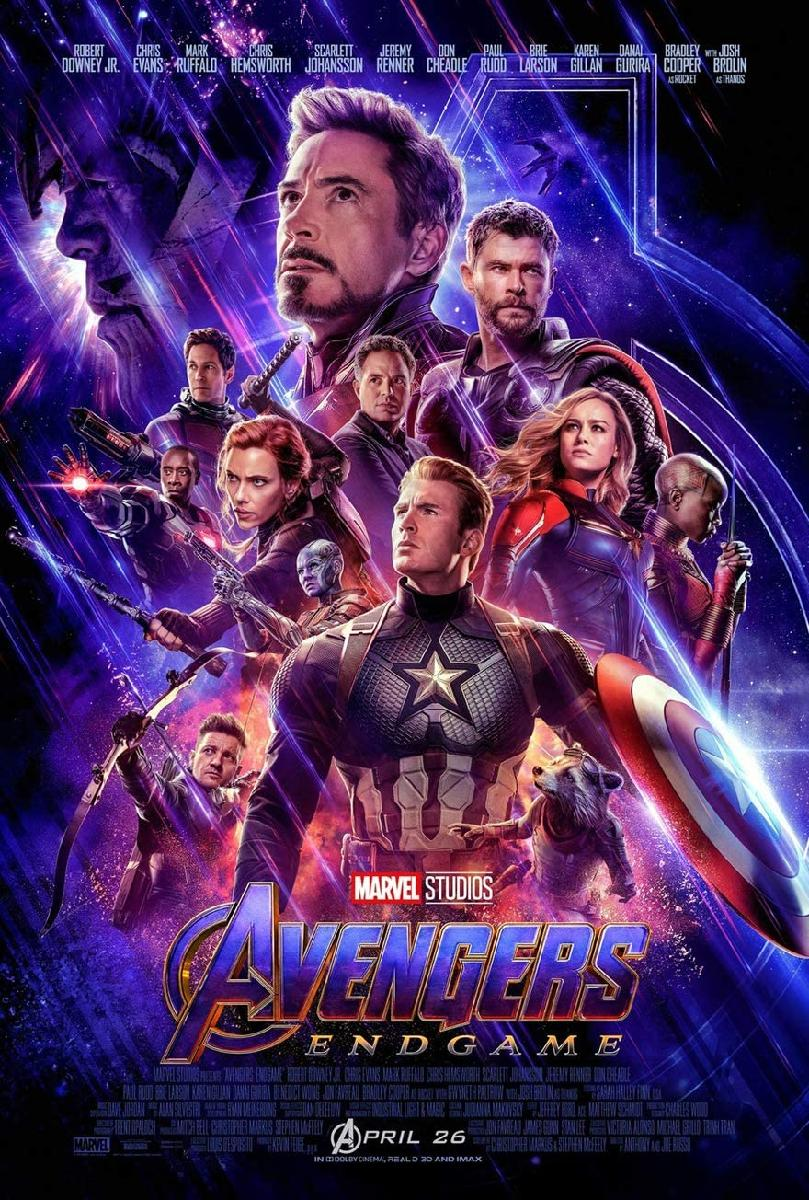

## QUICK FACTS:


fprintf('%s is directed by:',(latest_movie_title))

Avengers: Endgame is directed by:

celldisp(movie_director_name,'Director_name');

 
Director_name{1} =
 
Anthony Russo
 
 
Director_name{2} =
 
Joe Russo
 



if find(r == latest_movie)
    fprintf('%s is a movie for matured audiences as the movie has R-rating.',(latest_movie_title))
else
    fprintf('%s is a movie for most audiences as it is not an R-rated movie',(latest_movie_title))
end

Avengers: Endgame is a movie for most audiences as it is not an R-rated movie


fprintf('One of the cast members %s has played in %d movies with the director(s).',person_tog,together)

One of the cast members Mark Ruffalo has played in 2 movies with the director(s).

fprintf('Out of %d countries represented in the database, %s is represented by %s.',attributes_countries...
    ,latest_movie_title,movies(latest_movie).countries)

Out of 106 countries represented in the database, Avengers: Endgame is represented by US.

[people movie_list] = most_self_directed(directors,actors);


fprintf('Considering %s is a big HIT, more movies like this can be anticipated in the future.',(latest_movie_title))

Considering Avengers: Endgame is a big HIT, more movies like this can be anticipated in the future.


one_director = movie_director_name{1};

fprintf("%s hasn't made enough appearances in his movie(or at all). Considering there are people like " + ...
    "%s who have featured in %d of thier movies.",one_director,persons(people).name,length(movie_list))

Anthony Russo hasn't made enough appearances in his movie(or at all). Considering there are people like M. Night Shyamalan who have featured in 8 of thier movies.

fprintf('So maybe we can expect him to make appearances in his future movies!')

So maybe we can expect him to make appearances in his future movies!


movie_rating = movies(latest_movie).rating;

movie_release_date = str2double(movies(latest_movie).release(3:4));
avg_rating = ratings(movie_release_date);

fprintf("Avengers movies always have great ratings! Here's the comparison between rating of the latest movie..." + ...
    "and the year's average.")

Avengers movies always have great ratings! Here's the comparison between rating of the latest movie...and the year's average.

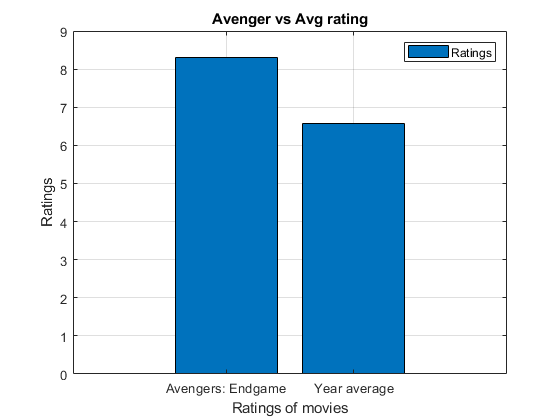


x = [1,2];
y= [movie_rating,avg_rating];
bar(x,y)
set(gca,'xTicklabel', {latest_movie_title, 'Year average'})
grid on
legend('Ratings')
title('Avenger vs Avg rating')
xlabel('Ratings of movies')
ylabel('Ratings')

### To check out news about the new or upcoming Marvel movies check [this](https://www.denofgeek.com/movies/marvel-movies-release-date-schedule-calendar-timeline/)!